# COVID-19 spread

## Data

breakdown = false;
if breakdown
    regione="Abruzzo";
    data_location = urlwrite("https://raw.githubusercontent.com/pcm-dpc/COVID-19/master/dati-regioni/dpc-covid19-ita-regioni.csv","./dati.csv") ;
else
    data_location = urlwrite("https://raw.githubusercontent.com/pcm-dpc/COVID-19/master/dati-andamento-nazionale/dpc-covid19-ita-andamento-nazionale.csv","./dati.csv") ;
end


dati=readtable(data_location);
delete dati.csv

if breakdown
    dati = dati(dati.denominazione_regione==regione, :);
end
dati = dati(:,{'data','totale_casi'});
dati.data = datetime(dati.data,"Format","uuuu-MM-dd'T'HH:mm:ss");

disp(dati)

           data            totale_casi
    ___________________    ___________

    2020-02-24T18:00:00         229   
    2020-02-25T18:00:00         322   
    2020-02-26T18:00:00         400   
    2020-02-27T18:00:00         650   
    2020-02-28T18:00:00         888   
    2020-02-29T18:00:00        1128   
    2020-03-01T18:00:00        1694   
    2020-03-02T18:00:00        2036   
    2020-03-03T18:00:00        2502   
    2020-03-04T18:00:00        3089   
    2020-03-05T18:00:00        3858   
    2020-03-06T18:00:00        4636   
    2020-03-07T18:00:00        5883   
    2020-03-08T18:00:00        7375   
    2020-03-09T18:00:00        9172   
    2020-03-10T18:00:00       10149   
    2020-03-11T17:00:00       12462   
    2020-03-12T17:00:00       15113   
    2020-03-13T17:00:00       17660   
    2020-03-14T17:00:00       21157   
    2020-03-15T17:00:00       24747   
    2020-03-16T17:00:00       2798

confirmed_cases = dati.totale_casi;
day_num = datenum(dati.data - dati.data(1));
delta = finite_difference(confirmed_cases);
CURRENT = day_num(end);

## Data fitting

[linfit, lin_r] = fit(day_num, confirmed_cases, 'poly1');
[expfit, exp_r] = fit(day_num, confirmed_cases, 'exp1');
[logfit, log_r] = logisticFit(day_num, confirmed_cases);

## Plotting

### Linear fitting

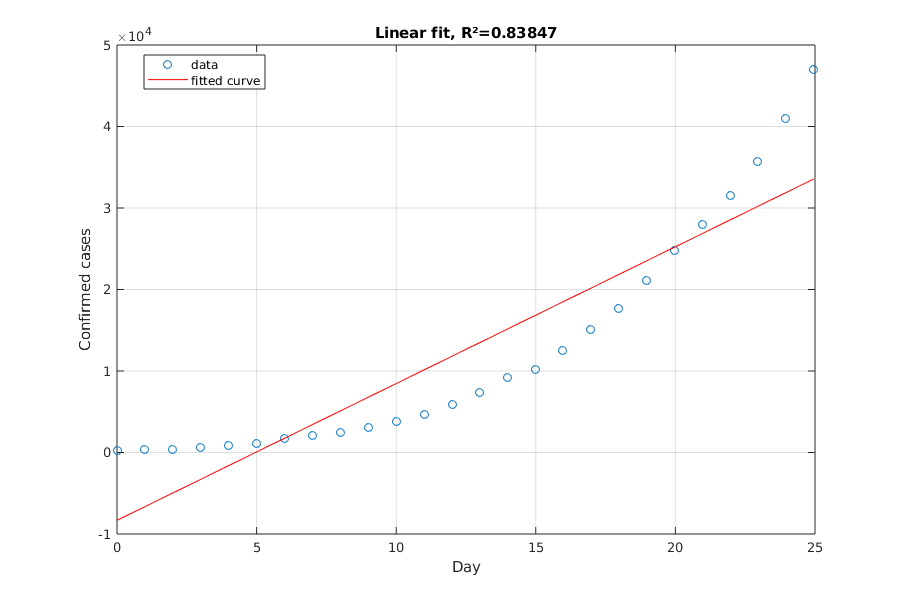

figure("Name",'linear', 'Position', [10 10 900 600]);

plot(linfit, day_num, confirmed_cases, "o")
grid on

title("Linear fit, R²="+lin_r.rsquare)
ylabel("Confirmed cases")
xlabel("Day")
legend({'data','fitted curve'},"Location","best")



disp("There are, on average, "+linfit.p1+" new cases each day.")

There are, on average, 1678.4396 new cases each day.


### Exponential fitting

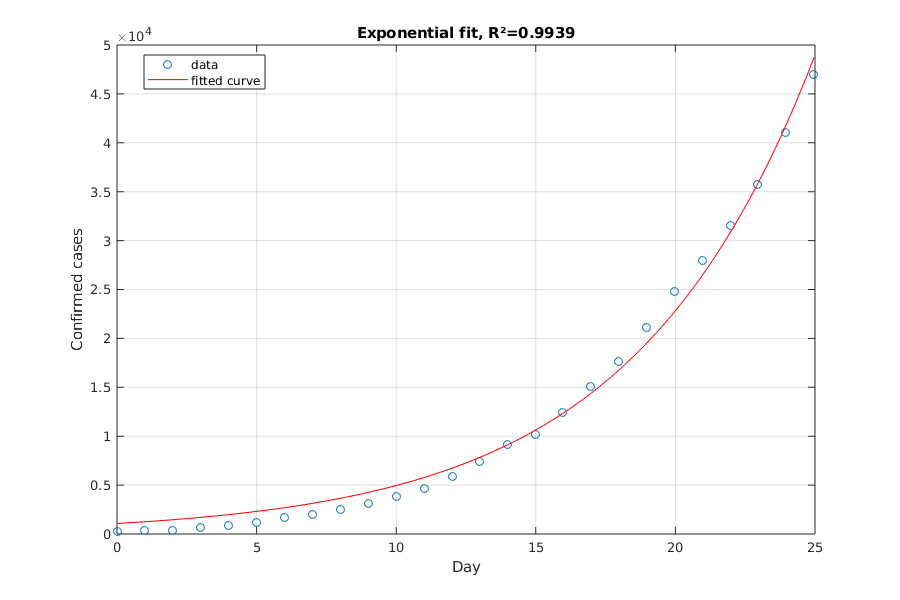

figure("Name",'exp1', 'Position', [10 10 900 600]);

plot(expfit, day_num, confirmed_cases, "o")
grid on

title("Exponential fit, R²="+exp_r.rsquare)
ylabel("Confirmed cases")
xlabel("Day")
legend({'data','fitted curve'},"Location","best")



disp("+"+expfit.b*100+"% new confirmed cases each day")

+15.2705% new confirmed cases each day


disp("Predicted new cases for tomorrow: "+round(expfit(CURRENT+1)-confirmed_cases(end)))

Predicted new cases for tomorrow: 9700


## Three parameters logistic fitting

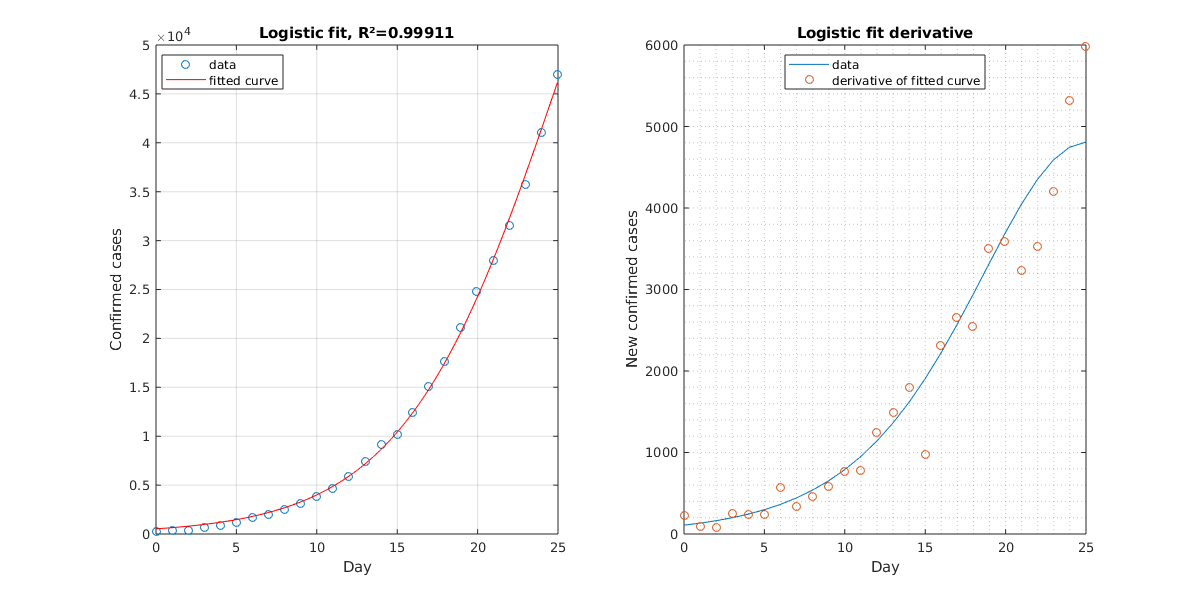

figure("Name",'log1', 'Position', [10 10 1200 600]);

subplot(1,2,1);
plot(logfit, day_num, confirmed_cases, "o")
grid on

title("Logistic fit, R²="+log_r.rsquare)
ylabel("Confirmed cases")
xlabel("Day")
legend({'data','fitted curve'},"Location","best")

subplot(1,2,2);
derivative = differentiate(logfit, day_num);
plot(day_num,derivative);



hold on
scatter(day_num, delta);
legend({'data','derivative of fitted curve'},"Location","best")

hold off
grid minor

title("Logistic fit derivative")
ylabel("New confirmed cases")
xlabel("Day")


[rho, pval] = corr(delta,derivative);
disp("Correlation of the derivative with actual icreases: "+rho);

Correlation of the derivative with actual icreases: 0.96989


disp("P-value: "+pval);

P-value: 3.1391e-16


disp("");
disp("Predicted total confirmed cases tomorrow: "+round(logfit(CURRENT+1)));

Predicted total confirmed cases tomorrow: 50930


disp("Predicted increase in cases tomorrow:     "+round(differentiate(logfit,CURRENT+1)));

Predicted increase in cases tomorrow:     4767


## Future projections

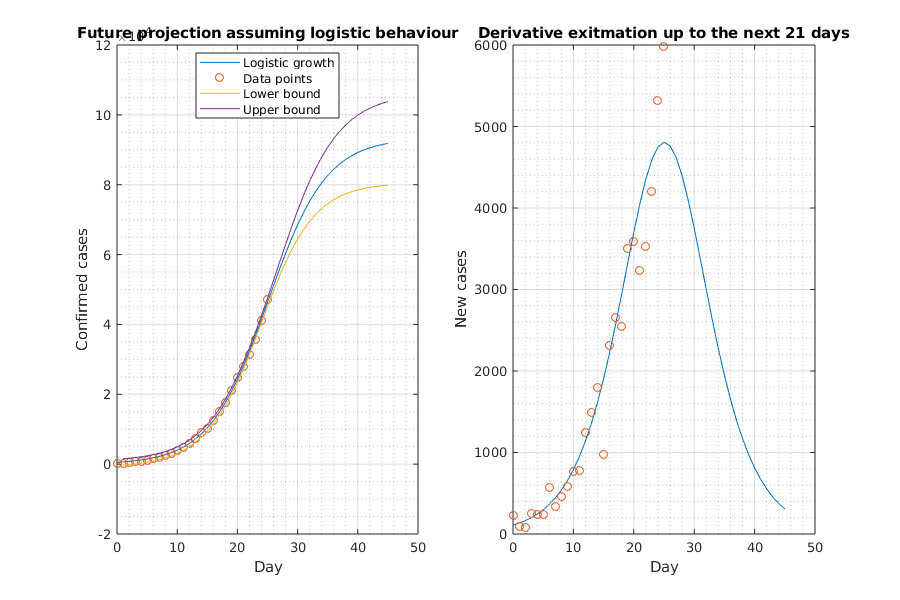

look_ahead_days = 21;
compare=false;
error_bars=true;

figure("Name","future1", 'Position', [10 10 900 600]);

subplot(1,2,1);
plot(0:(CURRENT+look_ahead_days),logfit(0:(CURRENT+look_ahead_days)))
hold on


grid on
grid minor
title("Future projection assuming logistic behaviour")
ylabel("Confirmed cases")
xlabel("Day")
scatter(day_num,confirmed_cases)

legend({'Logistic growth','Data points'}, "Location","best");

if compare
    plot(0:(CURRENT+look_ahead_days),expfit(0:(CURRENT+look_ahead_days)))
    title("Future projection logistic vs exponential")
    legend({'Logistic growth','Data points', 'Exponential growth'}, "Location","best");
end
if error_bars
    log_ci = predint(logfit,1:(CURRENT+look_ahead_days),0.95);
    plot(1:(CURRENT+look_ahead_days),log_ci,'LineWidth',0.001);
    legend({'Logistic growth','Data points','Lower bound','Upper bound'}, "Location","best");

end
hold off
subplot(1,2,2)
plot(0:(CURRENT+look_ahead_days),differentiate(logfit, 0:(CURRENT+look_ahead_days)));
hold on
scatter(day_num,delta);
grid on
grid minor

title("Derivative exitmation up to the next " + look_ahead_days+" days");
ylabel("New cases")
xlabel("Day")

if compare
    hold on
    plot(0:(CURRENT+look_ahead_days),differentiate(expfit, 0:(CURRENT+look_ahead_days)));
    hold off

end


## Comparison with past projections:

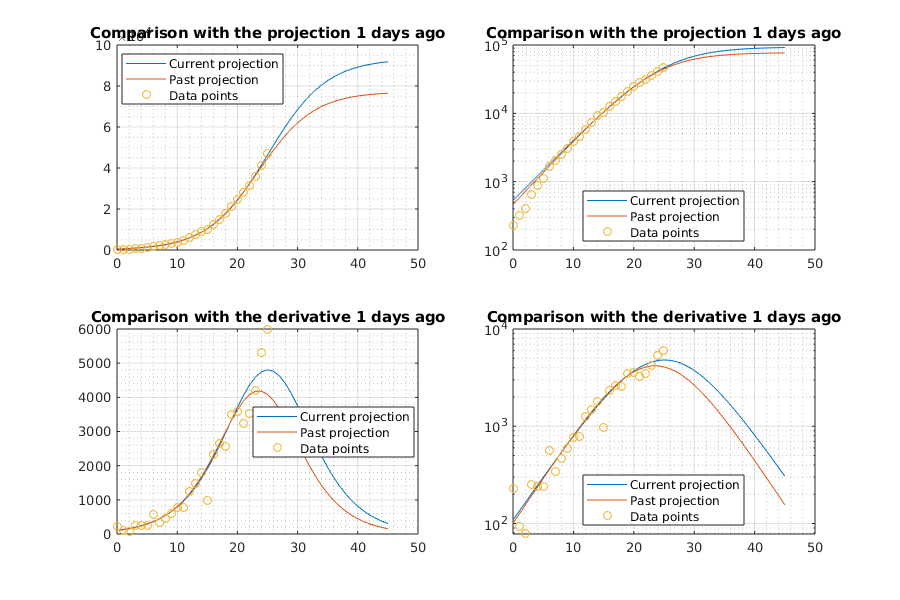

look_ahead_days = 21;
look_behind_days = 1;

model="Logistic";

reduced_day=day_num(1:(end-look_behind_days));
reduced_cases=confirmed_cases(1:(end-look_behind_days));

if model == "Logistic"
    model_current = logfit;
    model_past = logisticFit(reduced_day, reduced_cases );
else
    model_current = expfit;
    model_past = fit(reduced_day, reduced_cases, 'exp1');
end

figure("Name","future2", 'Position', [10 10 900 600]);

subplot(2,2,1);
plot(0:(CURRENT+look_ahead_days),model_current(0:(CURRENT+look_ahead_days)))
grid minor
grid on
hold on
plot(0:(CURRENT+look_ahead_days),model_past(0:(CURRENT+look_ahead_days)))
scatter(day_num, confirmed_cases)
title("Comparison with the projection "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
hold off


subplot(2,2,2);
semilogy(0:(CURRENT+look_ahead_days),model_current(0:(CURRENT+look_ahead_days)))
grid minor
grid on
hold on
semilogy(0:(CURRENT+look_ahead_days),model_past(0:(CURRENT+look_ahead_days)))
scatter(day_num, confirmed_cases)
title("Comparison with the projection "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
hold off


subplot(2,2,3);
plot(0:(CURRENT+look_ahead_days),differentiate(model_current, 0:(CURRENT+look_ahead_days)));
hold on
plot(0:(CURRENT+look_ahead_days),differentiate(model_past, 0:(CURRENT+look_ahead_days)));
hold on
scatter(day_num,delta);
title("Comparison with the derivative "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
grid minor
grid on
hold off


subplot(2,2,4);
semilogy(0:(CURRENT+look_ahead_days),differentiate(model_current, 0:(CURRENT+look_ahead_days)));
hold on
semilogy(0:(CURRENT+look_ahead_days),differentiate(model_past, 0:(CURRENT+look_ahead_days)));
hold on
scatter(day_num,delta);
title("Comparison with the derivative "+look_behind_days+" days ago");
legend({'Current projection','Past projection','Data points'}, "Location","best");
grid minor
grid on
hold off

function [difference] = finite_difference(x)
    subtract = zeros(length(x));
    subtract = subtract(:,1);
    subtract(2:end)=x(1:(end-1));
    difference = x-subtract;
end